## Simulation Environment

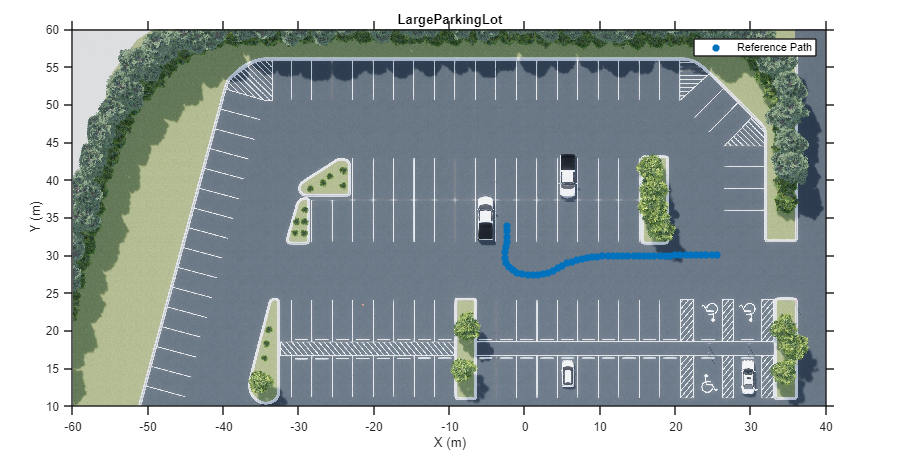

% Load reference path
data = load("ReferencePathForward.mat");

refPosesX = data.ReferencePathForward.refPosesX;
refPosesY = data.ReferencePathForward.refPosesY;
refPosesT = data.ReferencePathForward.refPosesT;

sceneName = "LargeParkingLot";
hScene = figure;
helperShowSceneImage(sceneName);
hold on
scatter(refPosesX(:,2),refPosesY(:,2), [],"filled",DisplayName="Reference Path");
xlim([-60 40])
ylim([10 60])
hScene.Position = [100 100 1000 500]; % Resize figure
legend
hold off

## Creating NDT Map from Prebuilt Point Cloud Map

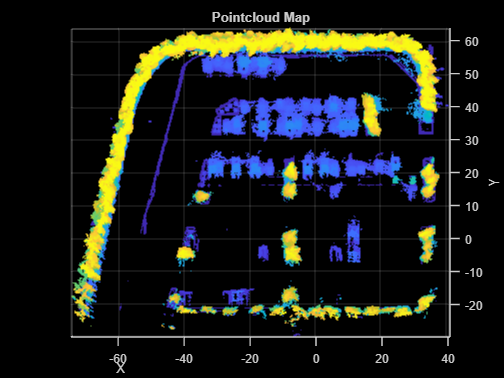

load("parkingLotPCMapPoints.mat");
figure
pcshow(ptCloudMapPoints)
view(2)
title("Pointcloud Map")
xlabel("X")
ylabel("Y")

Superimpose the point cloud map on the top-view image of the scene to visually examine how closely it resembles features in the scene.

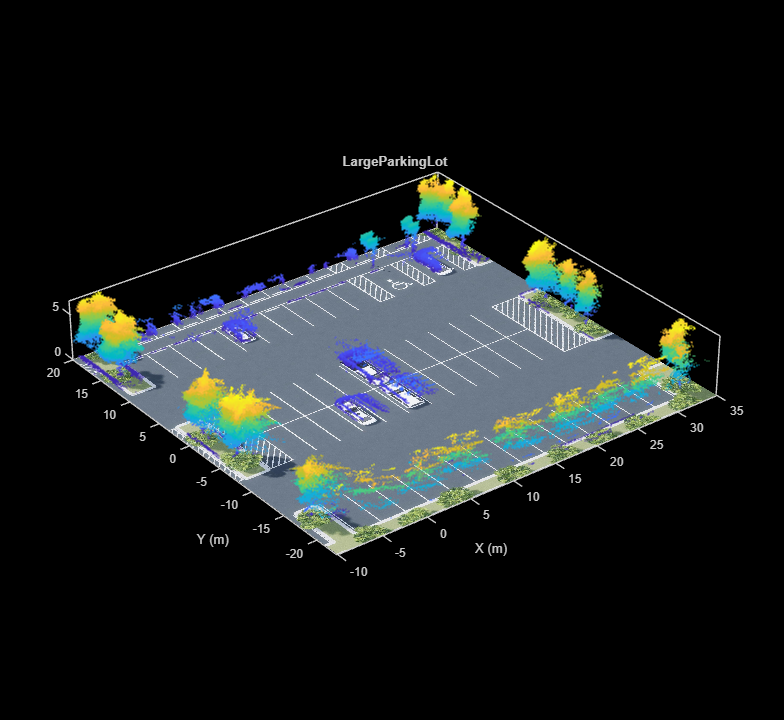

hMapOnScene = helperSuperimposeMapOnSceneImage('LargeParkingLot', ptCloudMapPoints);

Create an NDT map from the above point cloud map using [`pcmapndt`](docid:vision_ref#mw_0da8051d-0719-48c7-adb6-522c215ccf3a). 

Visualize the NDT map. 

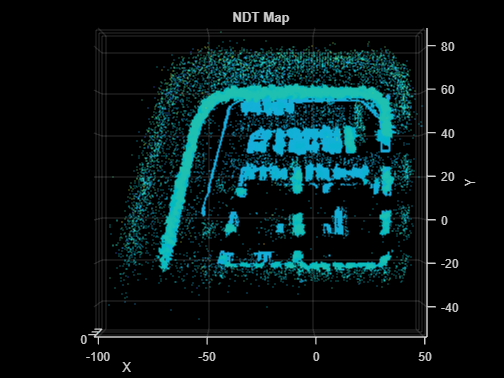

voxelSize = 1;
ndtMap = pcmapndt(pointCloud(ptCloudMapPoints),voxelSize);
figure
show(ndtMap)
view(2)
title("NDT Map")
xlabel("X")
ylabel("Y")

## Localize Using NDT Map

close(hScene)

if ~ispc
    error("Unreal Engine Simulation is supported only on Microsoft" ...
        + char(174) + " Windows" + char(174) + ".");
end

% Open model
modelName = "localizeUsingLidar";
open_system(modelName)
snapnow

% Run simulation
simOut = sim(modelName);

## Evaluate Localization Accuracy

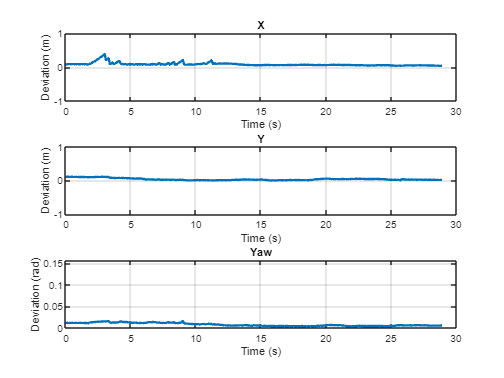

hFigMetrics = helperDisplayMetrics(simOut);

## Control Vehicle Using NDT Localization Estimate Feedback

% Specify vehicle dimensions
centerToFront = 1.104;
centerToRear  = 1.343;
frontOverhang = 0.828;
rearOverhang  = 0.589;
vehicleWidth  = 1.653;
vehicleHeight = 1.513;
vehicleLength = centerToFront + centerToRear + frontOverhang + rearOverhang;
hatchbackDims = vehicleDimensions(vehicleLength,vehicleWidth,vehicleHeight, ...
FrontOverhang=frontOverhang,RearOverhang=rearOverhang);

vehicleDims   = [hatchbackDims.Length hatchbackDims.Width hatchbackDims.Height];
vehicleColor  = [0.85 0.325 0.098];

% Load workspace variables for preplanned trajectory
refPoses   = data.ReferencePathForward.Trajectory.refPoses;
directions = data.ReferencePathForward.Trajectory.directions;
curvatures = data.ReferencePathForward.Trajectory.curvatures;
velocities = data.ReferencePathForward.Trajectory.velocities;
startPose  = refPoses(1,:);

% Open model
modelName = "localizeAndControlUsingLidar";
open_system(modelName)
snapnow

% Run simulation
sim(modelName);


close_system(modelName)

## Supporting Functions

`helperDisplayMetrics` disaplays metrics to assess the quality of localization.

function hFig = helperDisplayMetrics(simOut)

simTimes = simOut.logsout{1}.Values.Time;

xEst   = simOut.logsout{1}.Values.Data;
yEst   = simOut.logsout{2}.Values.Data;
yawEst = simOut.logsout{3}.Values.Data;

xTruth   = squeeze(simOut.logsout{4}.Values.Data(:,1,:));
yTruth   = squeeze(simOut.logsout{4}.Values.Data(:,2,:));
yawTruth = squeeze(simOut.logsout{5}.Values.Data(:,3,:));

xDeviation   = abs(xEst - xTruth);
yDeviation   = abs(yEst - yTruth);
yawDeviation = abs(helperWrapToPi(yawTruth - yawEst));

lim = [-1 1];
hFig = figure(Name="Metrics - Absolute Deviation");
subplot(3,1,1)
plot(simTimes, xDeviation,LineWidth=2);
ylim(lim)
grid on
title("X")
xlabel("Time (s)")
ylabel("Deviation (m)")

subplot(3,1,2)
plot(simTimes, yDeviation,LineWidth=2);
ylim(lim)
grid on
title("Y")
xlabel("Time (s)")
ylabel("Deviation (m)")

subplot(3,1,3)
plot(simTimes, yawDeviation,LineWidth=2);
ylim([0 pi/20])
grid on
title("Yaw")
xlabel("Time (s)")
ylabel("Deviation (rad)")
end

`helperSuperImposeMapOnSceneImage` superimposes point cloud map on scene image.

function hFig = helperSuperimposeMapOnSceneImage(sceneName, ptCloudAccum)

hFig = figure(Name="Point Cloud Map");
hIm = helperShowSceneImage(sceneName);

hold(hIm.Parent,"on")
pcshow(ptCloudAccum);
hold(hIm.Parent,"off")

xlim(hIm.Parent, [-10 35]);
ylim(hIm.Parent, [-23 20]);
end

`helperWrapToPi` wraps angles to the range $\lbrack -\pi \;\pi \rbrack$.

function angle = helperWrapToPi(angle)

idx = (angle < -pi) | (angle > pi);
angle(idx) = helperWrapTo2Pi(angle(idx) + pi) - pi;
end

`helperWrapTo2Pi` wraps angles to the range $\lbrack -2\pi \;2\pi \rbrack$.

function angle = helperWrapTo2Pi(angle)

pos = (angle>0);
angle = mod(angle, 2*pi);
angle(angle==0 & pos) = 2*pi;
end

*Copyright 2022 The MathWorks, Inc.*